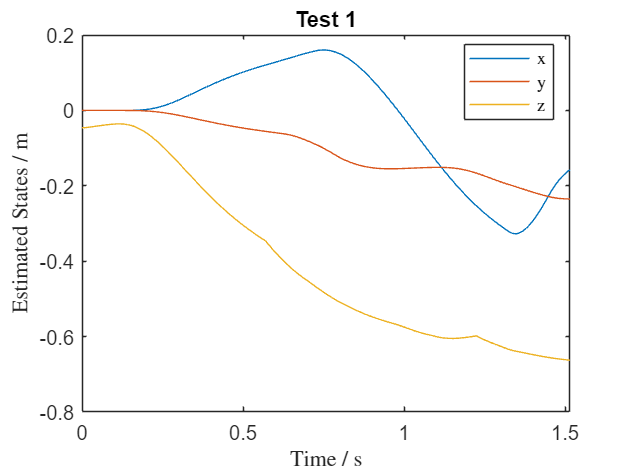

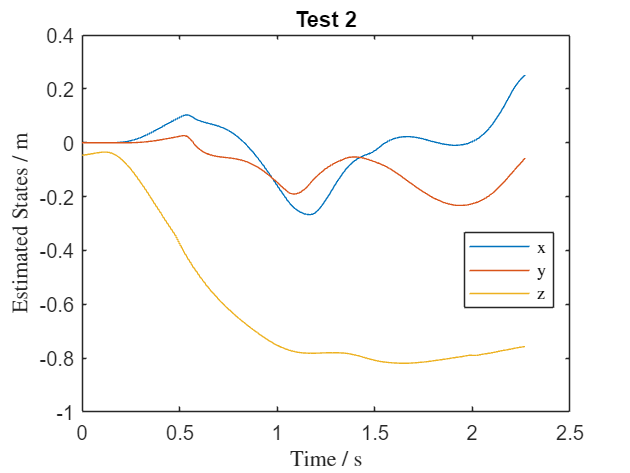

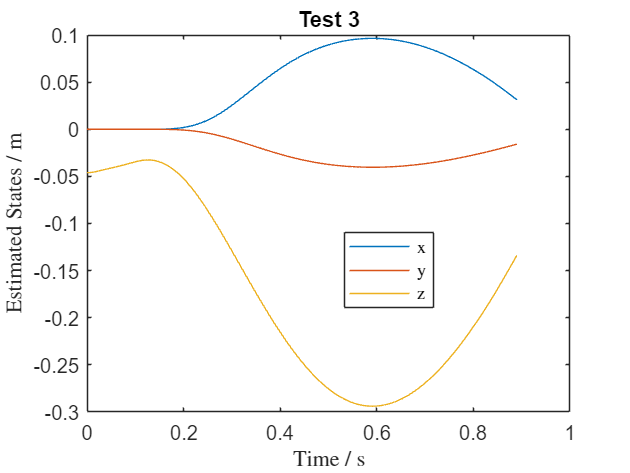

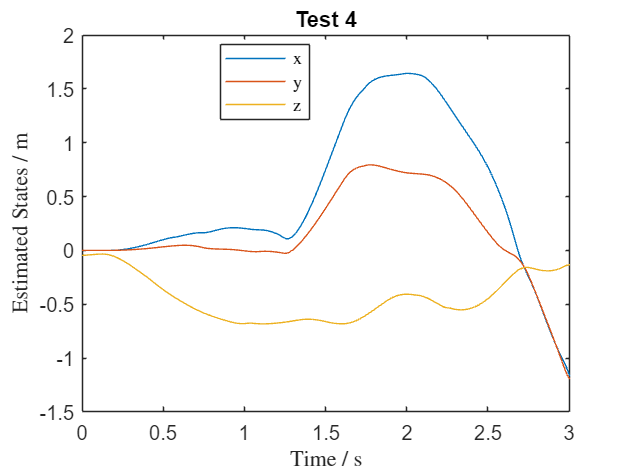

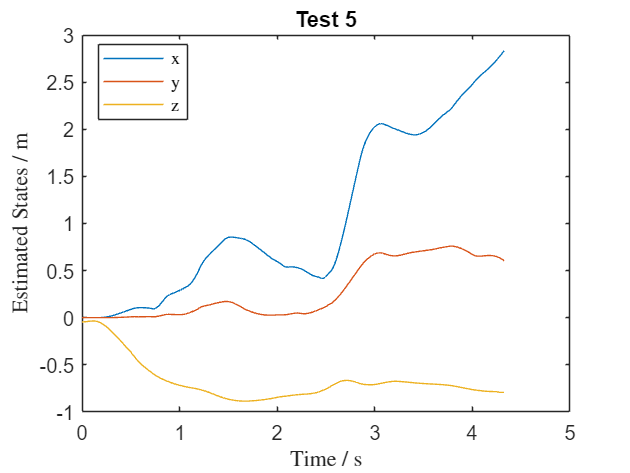

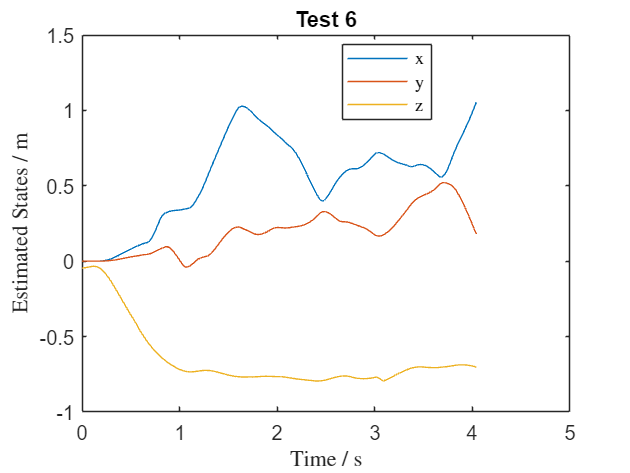

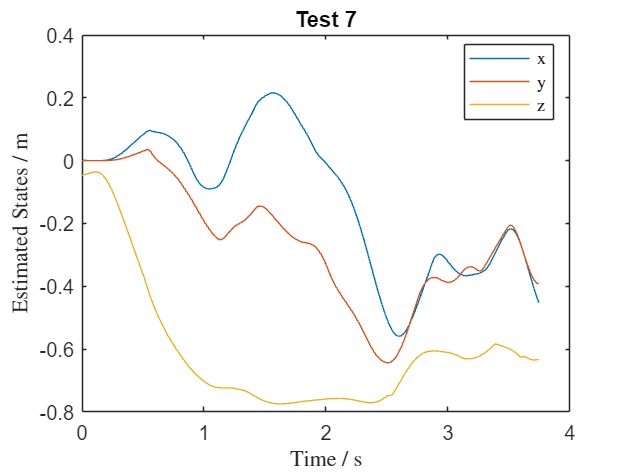

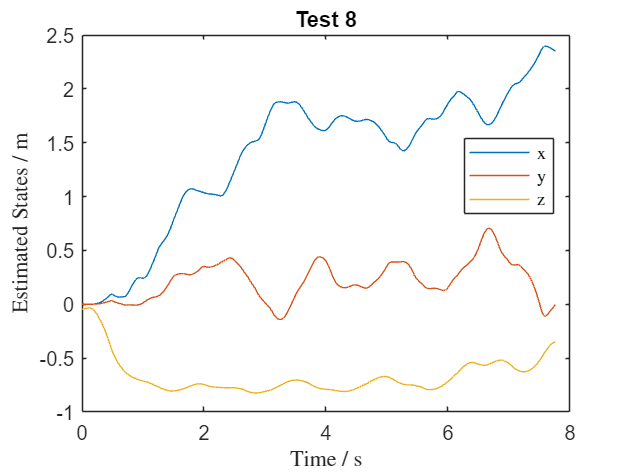

clear
clc
close all

for testNum = 1:22
    if any(testNum == [16 19])
        continue
    end
    % Generate the file name based on the current test number
    fileName = sprintf('Test%d.mat', testNum);
    
    % Load the file
    load(fileName);
    
    % Plotting
    figure;
    plot(rt_estimatedStates.time, rt_estimatedStates.signals.values(:, 1:3));
    
    % Customize plot
    title(sprintf('Test %d', testNum));
    xlabel('Time / s', Interpreter='latex');
    ylabel('Estimated States / m', Interpreter='latex');
    legend({'x', 'y', 'z'}, 'Location', 'Best',Interpreter='latex');
    
    % Optional: Adjust this pause if you want to manually close each figure before the next one opens
    % pause; % Uncomment this line if you want to pause after each plot to manually inspect it
end